## 数据预处理

t = out.MotorRPM.Time;
MotorRPM1 = out.MotorRPM.Data(:,1)*2*pi/60;
MotorRPM2 = out.MotorRPM.Data(:,2)*2*pi/60;
MotorRPM3 = out.MotorRPM.Data(:,3)*2*pi/60;
MotorRPM4 = out.MotorRPM.Data(:,4)*2*pi/60;

MotorRPM1_health = healthFlightData.MotorRPM.Data(:,1)*2*pi/60;
MotorRPM2_health = healthFlightData.MotorRPM.Data(:,2)*2*pi/60;
MotorRPM3_health = healthFlightData.MotorRPM.Data(:,3)*2*pi/60;
MotorRPM4_health = healthFlightData.MotorRPM.Data(:,4)*2*pi/60;
% 电机拉力系数
ModelParam_rotorCt = 1.345e-06;

## 故障下的电机转速曲线

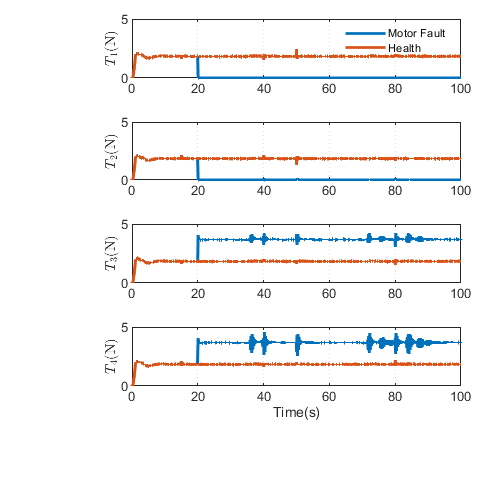

figure(1)
subplot(11,1,[1 2])
plot(t,MotorRPM1.^2*ModelParam_rotorCt,"Color",'#0072BD','LineWidth',2)
hold on
plot(t,MotorRPM1_health.^2*ModelParam_rotorCt,'Color','#D95319','LineWidth',2)
ylim([0 5]);
ylabel('$T_{1}$(N)','Interpreter',"latex")
legend('Motor Fault','Health','box','off','location',"northeast")

subplot(11,1,[4 5])
plot(t,MotorRPM2.^2*ModelParam_rotorCt,"Color",'#0072BD','LineWidth',2)
hold on
plot(t,MotorRPM2_health.^2*ModelParam_rotorCt,'Color','#D95319','LineWidth',2)
ylim([0 5]);
ylabel('$T_{2}$(N)','Interpreter',"latex")

subplot(11,1,[7 8])
plot(t,MotorRPM3.^2*ModelParam_rotorCt,"Color",'#0072BD','LineWidth',2)
hold on
plot(t,MotorRPM3_health.^2*ModelParam_rotorCt,'Color','#D95319','LineWidth',2)
ylim([0 5]);
ylabel('$T_{3}$(N)','Interpreter',"latex")

subplot(11,1,[10 11])
plot(t,MotorRPM4.^2*ModelParam_rotorCt,"Color",'#0072BD','LineWidth',2)
hold on
plot(t,MotorRPM4_health.^2*ModelParam_rotorCt,'Color','#D95319','LineWidth',2)
ylim([0 5]);
ylabel('$T_{4}$(N)','Interpreter',"latex")
xlabel('Time(s)')